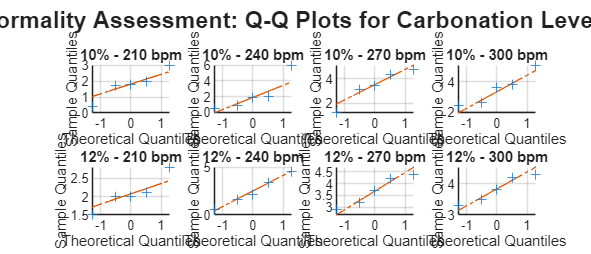

clear; clc; close all;

% === Input sample data ===
% --- 10% Carbonation ---
speed210_10 = [0.4, 2.0, 3.0, 1.7, 1.8];
speed240_10 = [0.5, 2.0, 0.9, 1.9, 6.0];
speed270_10 = [4.7, 3.4, 1.2, 3.1, 4.3];
speed300_10 = [3.6, 2.6, 2.4, 3.8, 5.1];

% --- 12% Carbonation ---
speed210_12 = [1.5, 2.0, 2.8, 2.1, 2.0];
speed240_12 = [3.4, 2.1, 0.6, 4.5, 1.6];
speed270_12 = [4.4, 4.2, 3.2, 3.7, 2.9];
speed300_12 = [4.3, 3.3, 4.2, 3.8, 3.5];

% % --- Apply log transformation for 10% Carbonation ---
% speed210_10 = log(speed210_10);
% speed240_10 = log(speed240_10);
% speed270_10 = log(speed270_10);
% speed300_10 = log(speed300_10);
% 
% % --- Apply log transformation for 12% Carbonation ---
% speed210_12 = log(speed210_12);
% speed240_12 = log(speed240_12);
% speed270_12 = log(speed270_12);
% speed300_12 = log(speed300_12);


%% === Q-Q Plots to check the normality ===

figure('Color','w','Position',[100 100 1400 600]);

% === 10% Carbonation ===
subplot(2,4,1);
qqplot(speed210_10);
title('10% - 210 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,2);
qqplot(speed240_10);
title('10% - 240 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,3);
qqplot(speed270_10);
title('10% - 270 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,4);
qqplot(speed300_10);
title('10% - 300 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

% === 12% Carbonation ===
subplot(2,4,5);
qqplot(speed210_12);
title('12% - 210 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,6);
qqplot(speed240_12);
title('12% - 240 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,7);
qqplot(speed270_12);
title('12% - 270 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

subplot(2,4,8);
qqplot(speed300_12);
title('12% - 300 bpm');
xlabel('Theoretical Quantiles');
ylabel('Sample Quantiles');
grid on;

% --- title ---
sgtitle('Normality Assessment: Q-Q Plots for Carbonation Levels', ...
    'FontSize', 14, 'FontWeight', 'bold');



%% === Levene's Test to check the equality in variance ===

fprintf('\n========================================\n');

fprintf('2. Equal Variance: Levene''s Test\n');

2. Equal Variance: Levene's Test


fprintf('========================================\n');


% === Combine for analysis (optional: test separately) ===
% Here we'll test 10% and 12% separately to check variance equality among speeds

%% --- Levene Test for 10% Carbonation ---
fprintf('\n--- 10%% Carbonation ---\n');


--- 10% Carbonation ---


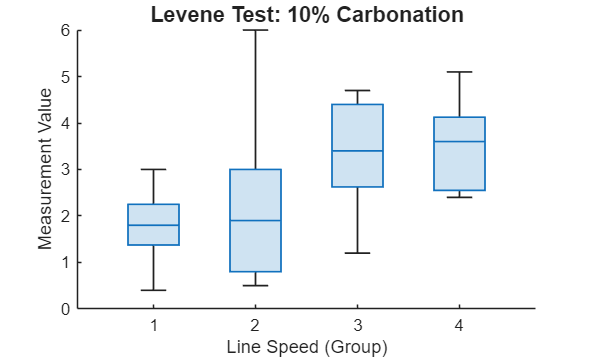


n210_10 = length(speed210_10);
n240_10 = length(speed240_10);
n270_10 = length(speed270_10);
n300_10 = length(speed300_10);

data10 = [speed210_10'; speed240_10'; speed270_10'; speed300_10'];
group10 = [ones(n210_10,1); 2*ones(n240_10,1); 3*ones(n270_10,1); 4*ones(n300_10,1)];

figure('Name','Equal Variance Check (10%)','Color','w');
boxchart(categorical(group10), data10);
xlabel('Line Speed (Group)');
ylabel('Measurement Value');
title('Levene Test: 10% Carbonation','FontSize',13);


[p10, tbl10] = vartestn(data10, group10, 'TestType','LeveneAbsolute','Display','off');
disp(tbl10);

    fstat: 0.8626
       df: [3 16]



fprintf('Levene Test p-value (10%%) = %.4f\n', p10);

Levene Test p-value (10%) = 0.4806



if p10 > 0.05
    fprintf('→ Fail to reject H₀: Equal variances assumed (p > 0.05)\n');
    fprintf('→ Proceed with standard two-way ANOVA\n');
else
    fprintf('→ Reject H₀: Variances are NOT equal (p < 0.05)\n');
    fprintf('→ Consider using Welch''s ANOVA or transformation\n');
end

→ Fail to reject H₀: Equal variances assumed (p > 0.05)


→ Proceed with standard two-way ANOVA




%% --- Levene Test for 12% Carbonation ---
fprintf('\n--- 12%% Carbonation ---\n');


--- 12% Carbonation ---


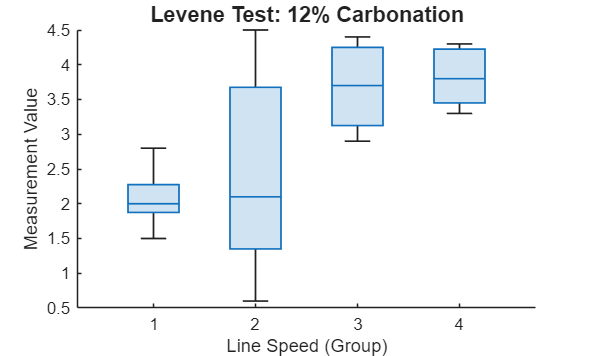


n210_12 = length(speed210_12);
n240_12 = length(speed240_12);
n270_12 = length(speed270_12);
n300_12 = length(speed300_12);

data12 = [speed210_12'; speed240_12'; speed270_12'; speed300_12'];
group12 = [ones(n210_12,1); 2*ones(n240_12,1); 3*ones(n270_12,1); 4*ones(n300_12,1)];

figure('Name','Equal Variance Check (12%)','Color','w');
boxchart(categorical(group12), data12);
xlabel('Line Speed (Group)');
ylabel('Measurement Value');
title('Levene Test: 12% Carbonation','FontSize',13);


[p12, tbl12] = vartestn(data12, group12, 'TestType','LeveneAbsolute','Display','off');
disp(tbl12);

    fstat: 4.7354
       df: [3 16]



fprintf('Levene Test p-value (12%%) = %.4f\n', p12);

Levene Test p-value (12%) = 0.0150



if p12 > 0.05
    fprintf('→ Fail to reject H₀: Equal variances assumed (p > 0.05)\n');
    fprintf('→ Proceed with standard one-way ANOVA\n');
else
    fprintf('→ Reject H₀: Variances are NOT equal (p < 0.05)\n');
    fprintf('→ Consider using Welch''s ANOVA or transformation\n');
end

→ Reject H₀: Variances are NOT equal (p < 0.05)


→ Consider using Welch's ANOVA or transformation







fprintf('\n========================================\n');

fprintf('3. Two-Way ANOVA with replication\n');

3. Two-Way ANOVA with replication


fprintf('========================================\n');


% Step 1. Define data cube: LineSpeed × Carbonation × Replicates (4×2×5)
Fill(:,:,1) = [speed210_10(1) speed210_12(1);
               speed240_10(1) speed240_12(1);
               speed270_10(1) speed270_12(1);
               speed300_10(1) speed300_12(1)];
Fill(:,:,2) = [speed210_10(2) speed210_12(2);
               speed240_10(2) speed240_12(2);
               speed270_10(2) speed270_12(2);
               speed300_10(2) speed300_12(2)];
Fill(:,:,3) = [speed210_10(3) speed210_12(3);
               speed240_10(3) speed240_12(3);
               speed270_10(3) speed270_12(3);
               speed300_10(3) speed300_12(3)];
Fill(:,:,4) = [speed210_10(4) speed210_12(4);
               speed240_10(4) speed240_12(4);
               speed270_10(4) speed270_12(4);
               speed300_10(4) speed300_12(4)];
Fill(:,:,5) = [speed210_10(5) speed210_12(5);
               speed240_10(5) speed240_12(5);
               speed270_10(5) speed270_12(5);
               speed300_10(5) speed300_12(5)];

LineSpeeds = {'210 bpm','240 bpm','270 bpm','300 bpm'};
Carbonation = {'10%','12%'};

% Step 2. Verify dimensions
disp('Data cube dimensions (LineSpeed × Carbonation × Replicates):');

Data cube dimensions (LineSpeed × Carbonation × Replicates):


disp(size(Fill));

     4     2     5




% Step 3. ✅ Correct reshaping for MATLAB's expected order
% MATLAB expects: all reps of LineSpeed1 first, then LineSpeed2, ...
% So permute dimensions as (rep, speed, carbonation)
Y = reshape(permute(Fill, [3 1 2]), [], 2);

% Step 4. Perform Two-Way ANOVA with replication
[p, tbl, stats] = anova2(Y, 5, 'off');  % 5 replicates per cell
disp('--- Two-Way ANOVA (With Replication) Results ---');

--- Two-Way ANOVA (With Replication) Results ---


disp(tbl);

    {'Source'     }    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'    }    {[ 0.8123]}    {[ 1]}    {[  0.8123]}    {[  0.5497]}    {[  0.4639]}
    {'Rows'       }    {[21.8747]}    {[ 3]}    {[  7.2916]}    {[  4.9342]}    {[  0.0063]}
    {'Interaction'}    {[ 0.0388]}    {[ 3]}    {[  0.0129]}    {[  0.0087]}    {[  0.9989]}
    {'Error'      }    {[47.2880]}    {[32]}    {[  1.4777]}    {0×0 double}    {0×0 double}
    {'Total'      }    {[70.0138]}    {[39]}    {0×0 double}    {0×0 double}    {0×0 double}




% Step 5. Interpret results
fprintf('\nInterpretation:\n');


Interpretation:


fprintf('p(Carbonation)    = %.4f\n', p(1));

p(Carbonation)    = 0.4639


fprintf('p(Line speed)   = %.4f\n', p(2));

p(Line speed)   = 0.0063


fprintf('p(Interaction)   = %.4f\n', p(3));

p(Interaction)   = 0.9989



if p(1) < 0.05
    fprintf('→ Significant difference between Carbonation.\n');
else
    fprintf('→ No significant difference between Carbonation.\n');
end

→ No significant difference between Carbonation.


if p(2) < 0.05
    fprintf('→ Significant difference between Line speed.\n');
else
    fprintf('→ No significant difference between Line speed.\n');
end

→ Significant difference between Line speed.


if p(3) < 0.05
    fprintf('→ Significant interaction effect (Carbonation × Line speed).\n');
else
    fprintf('→ No significant interaction effect detected.\n');
end

→ No significant interaction effect detected.


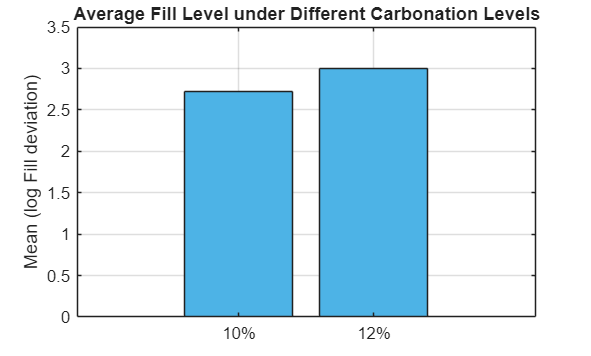


% Step 6. Visualization
meanFill = mean(Y);
bar(meanFill, 'FaceColor',[0.3 0.7 0.9]);
title('Average Fill Level under Different Carbonation Levels');
xticklabels(Carbonation);
ylabel('Mean (log Fill deviation)');
grid on;